(1) Se cargan los datos del archivo. Se extraen todos los canales del EEG, creando para ello una matriz que los contenga:

datos = edfread('PN00-1.edf');
info_archivo = edfinfo("PN00-1.edf");
nombres_canales = datos.Properties.VariableNames;

n_muestras = length(cell2mat(datos.(nombres_canales{1})));
num_canales = length(nombres_canales);
s = zeros(n_muestras, num_canales);

for i = 1:num_canales
    s(:, i) = cell2mat(datos.(nombres_canales{i}));
end

*Eliminación de la componente continua restando el valor medio a cada punto de la señal*

s_sin_continua = s - mean(s, 1);

Tiempo y frecuencia de muestreo:

f_muestreo=info_archivo.NumSamples(1)/seconds(info_archivo.DataRecordDuration); %se calcula la frecuencia de muestreo en Hz dividiendo la cantidad de muestras recogidas entre la duración, en segundos, de la adquisición;
t_muestreo=1/f_muestreo;

**Filtrado de la señal**

En primer lugar, se empleará un filtro Notch para eliminar las interferencias causadas por la red eléctrica (50 Hz). Es un paso elimina banda que deja pasar todas las frecuencias menos las que se encuentran en una banda muy estrecha. Se emplea la función filtfilt() para eliminar el desfase.

canal_a_ver = 1; %modificando esta variable se cambia el canal que se quiere representar, evitando la representación de todos los canales juntos para que el ordenador no se cuelgue
d  = designfilt('bandstopiir', 'FilterOrder', 4, 'HalfPowerFrequency1', 49, 'HalfPowerFrequency2', 51, 'SampleRate', f_muestreo);
s_sin_continua(:, canal_a_ver) = filtfilt(d, s_sin_continua(:, canal_a_ver));

Ahora se aplicará un filtro paso alto para elimiinar las frecuencias por debajo de 0,5 Hz, correspondientes a la respiración y movimiento

% Elimina todo por debajo de 0.5 Hz (respiración, deriva lenta, movimiento)
hp = designfilt('highpassiir', 'FilterOrder', 4, ...
     'HalfPowerFrequency', 0.5, 'SampleRate', f_muestreo);
s_sin_continua(:, canal_a_ver) = filtfilt(hp, s_sin_continua(:, canal_a_ver));

Se empleará la transformada de Wavelet para separar las distintas frecuencias de la señal.

La correspondencia nivel-banda para la transformada Wavelet depende de la frecuencia de muestreo. Se ha empleado la siguiente fórmula para ajustar los distintos niveles: [Fs/2^(k+1), Fs/2^k]

Se realizará la umbralización de los niveles 3 y 4, debido a que existen frecuencias muy altas que deben eliminarse. Umbralizar consiste en eliminar los coeficientes que superen un cierto valor límite o umbral, asumiento que esos coeficientes corresponden a ruido o artefactos. Los coeficientes wavelet que tienen una amplitud estadísticamente anómala respecto al resto de la señal son probablemente artefactos, no actividad cerebral. Para calcular el umbral se emplea la mediana de los coeficientes dividida entre un factor de corrección.

segundos_a_procesar = 10;        
max_muestras = round(segundos_a_procesar * f_muestreo);

n_total = size(s_sin_continua, 1);
s_sin_continua = s_sin_continua(1:min(max_muestras, n_total), :);
n_muestras=size(s_sin_continua, 1);
t=(0:n_muestras-1)*t_muestreo;


wt = modwt(s_sin_continua(:, canal_a_ver), 'db8'); %aplicación de la transformada de Wavelet discreta a la señal

for nivel = [3, 4]
    umbral = 3 * median(abs(wt(nivel,:))) / 0.6745;
    wt(nivel,:) = wthresh(wt(nivel,:), 's', umbral);
end 

wtrec = zeros(size(wt)); %creación de una matriz de ceros del mismo tamaño que wtrec, para reconstruir únicamente la banda de frecuencia asociada a una fila
wtrec(3,:) = wt(3,:); %copia el nivel dos de la descomposición en la mácara
eeg1gamma = imodwt(wtrec,'db8'); %aplicación de la transformada inversa
%>30Hz

%ahora, se hará lo mismo para cada nivel

wtrec = zeros(size(wt));
wtrec(4,:) = wt(4,:);
eeg1beta = imodwt(wtrec,'db8');
%13-30 Hz

wtrec = zeros(size(wt));
wtrec(5,:) = wt(5,:);
eeg1alpha = imodwt(wtrec,'db8');
%8-13 Hz

wtrec = zeros(size(wt));
wtrec(6,:) = wt(6,:);
eeg1theta = imodwt(wtrec,'db8');
%4-8 Hz

wtrec = zeros(size(wt));
wtrec(7,:) = wt(7,:);
wtrec(8,:) = wt(8,:);
wtrec(9,:) = wt(9,:);
eeg1delta = imodwt(wtrec, 'db8');
%0,5-4 Hz

**Representación de las ondas correspondientes a cada banda de frecuencia**

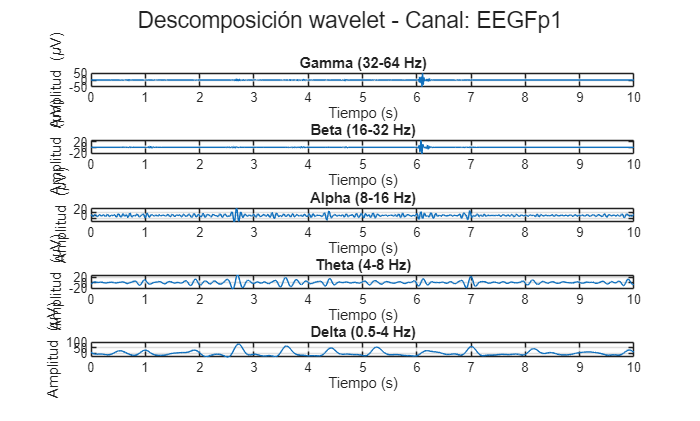

figure;
subplot(5,1,1);
plot(t, eeg1gamma);
title('Gamma (32-64 Hz)');
xlabel('Tiempo (s)'); ylabel('Amplitud (\muV)'); grid on;

subplot(5,1,2);
plot(t, eeg1beta);
title('Beta (16-32 Hz)');
xlabel('Tiempo (s)'); ylabel('Amplitud (\muV)'); grid on;

subplot(5,1,3);
plot(t, eeg1alpha);
title('Alpha (8-16 Hz)');
xlabel('Tiempo (s)'); ylabel('Amplitud (\muV)'); grid on;

subplot(5,1,4);
plot(t, eeg1theta);
title('Theta (4-8 Hz)');
xlabel('Tiempo (s)'); ylabel('Amplitud (\muV)'); grid on;

subplot(5,1,5);
plot(t, eeg1delta);
title('Delta (0.5-4 Hz)');
xlabel('Tiempo (s)'); ylabel('Amplitud (\muV)'); grid on;

sgtitle(['Descomposición wavelet - Canal: ' nombres_canales{canal_a_ver}]);